## Synthesis of Robust and stable controler from Desired response 

## Initizilation

clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);



## Filter

The controller is designed with only Wref, Wu =0, and Wz as passthrough

s=tf('s');
%Wz feedthrough filter
WZ = 1;
param = model.calculateWz(param,WZ,1);
%Ww lowpass filter 
WW = 2*pi*eye(4)*1/(s+2*pi);
param = model.calculateWw(param,WW,0);

%Wref
%lowpass filter wich result in a setling time of 10 min.  
wref =eye(4)*(1/(120*s+1))

wref =
 
  From input 1 to output...
           1
   1:  ---------
       120 s + 1
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
           1
   2:  ---------
       120 s + 1
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
           1
   3:  ---------
       120 s + 1
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
           1
   4:  ---------
       120 s + 1
 
Continuous-time transfer function.


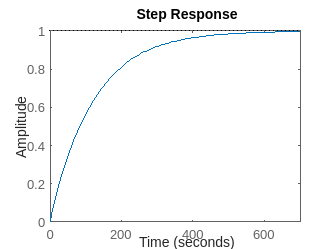

wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;
figure()
step(wref(1,1))


%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);


## Control

param = control.DesignProcedureRobustPerformanceAndRobustStabilityWeighted(param,1); 

Linear matrix variable 4x28 (full, real, 112 variables)
Coefficient range: 1 to 1


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0268
       solvertime: 0.1859
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|           0.56568|      8.2715e-11|
|   #2|        Matrix inequality|          0.036467|      1.6647e-12|
|   #3|        Matrix inequality|       -6.8219e-17|      7.6561e-12|
|   #4|   Elementwise inequality|            0.2295|      4.8655e-09|
|   #5|        Matrix inequality|          0.020197|      1.6456e-12|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

ans = NaN

gamma desired per


ans = 0.2295

gamma robust stab


ans = NaN

y_out =     2.3679   -0.2537    0.5556         0         0         0         0         0         0         0         0         0    1.1717   -1.0992   -2.3114    0.5603   -0.0000   -0.0000    0.0000    0.0000   -0.0660   -0.0041   -0.0151    0.0052   -0.0000   -0.0000   -0.0000   -0.0000
         0         0         0    1.9782   -0.1460   -0.0670         0         0         0         0         0         0   -0.3008    0.5095   -2.1018    0.6087   -0.0000   -0.0000    0.0000   -0.0000    0.0010    0.0132   -0.0119    0.0026   -0.0000   -0.0000   -0.0000   -0.0000
         0         0         0         0         0         0    1.7173   -0.1443    2.8112         0         0         0   -0.1952   -0.4088    5.4132   -0.8667    0.0000   -0.0000   -0.0000   -0.0000   -0.0015   -0.0030   -0.3522   -0.0053    0.0000    0.0000   -0.0000    0.0000
         0         0         0         0         0         0         0         0         0    1.8773   -0.2576   -0.1286   -0.0560    0.2931   -2.909

k =    17.7114    0.6609    0.2376         0         0         0         0         0         0         0         0         0
         0         0         0   36.0139    0.9681    0.4922         0         0         0         0         0         0
         0         0         0         0         0         0   48.0638    0.8875    0.6775         0         0         0
         0         0         0         0         0         0         0         0         0   45.6831    0.9873    0.6338


Eig of Q_hat


ans =     0.0202
    0.0358
    0.0406
    0.1041
    0.5837
    0.9382
    1.0757
    1.1842
    1.4118
    1.4306


## Simulate the linear response

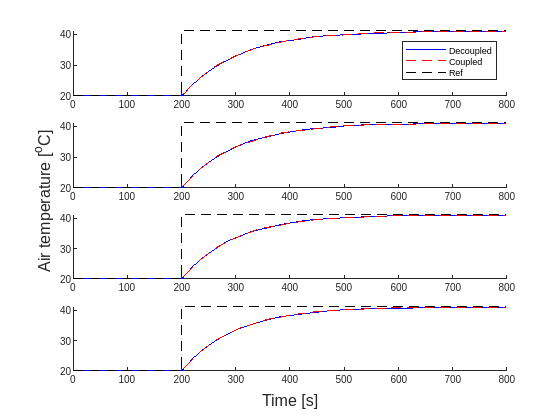

ans = struct with fields:
    time: [56×1 double]
      Tw: [56×4 double]
      Ta: [56×4 double]
       T: [56×4 double]


util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Only_Wref",0,800,21)

## Correcting the response by applying a fitted desired response 

## Filter

The controller is designed with only Wref, where Wref have been fitted to give the desired response, and  Wu =0 

s=tf('s');
%Wz feedthrough filter with a weight of 20.
param.model.Awz = zeros(4);
param.model.Bwz = zeros(4);
param.model.Cwz = zeros(4);
param.model.Dwz = 20*eye(4);

%Ww lowpass filter 
WW = 2*pi*eye(4)*1/(s+2*pi);
param = model.calculateWw(param,WW,0);

%Wref
%lowpass filter wich result in a setling time of 10 min.  
wref =eye(4)*(1/(120*s+1))

wref =
 
  From input 1 to output...
           1
   1:  ---------
       120 s + 1
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
           1
   2:  ---------
       120 s + 1
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
           1
   3:  ---------
       120 s + 1
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
           1
   4:  ---------
       120 s + 1
 
Continuous-time transfer function.


wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;

%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);


## Control

param = control.DesignProcedureRobustPerformanceAndRobustStabilityWeighted(param,1); 

Linear matrix variable 4x28 (full, real, 112 variables)
Coefficient range: 1 to 1


sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0306
       solvertime: 0.1931
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|          0.036334|      3.2574e-10|
|   #2|        Matrix inequality|         0.0043713|      5.1796e-12|
|   #3|        Matrix inequality|       -5.7914e-17|      2.3651e-11|
|   #4|   Elementwise inequality|            0.2295|      2.1568e-08|
|   #5|        Matrix inequality|         0.0016339|      5.1379e-12|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

ans = NaN

gamma desired per


ans = 0.2295

gamma robust stab


ans = NaN

y_out =     2.2096    0.0012    0.8545         0         0         0         0         0         0         0         0         0    1.5429   -0.9239   -1.6554    0.5716   -0.0000    0.0000   -0.0000   -0.0000   -0.1067   -0.0001   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000
         0         0         0    1.8805   -0.0025    0.4709         0         0         0         0         0         0   -0.9589    0.8412   -1.3990    0.0928   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0588   -0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000
         0         0         0         0         0         0    1.6943   -0.0060    1.1436         0         0         0   -0.7235   -0.5114    1.1864   -0.5497   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.1431   -0.0001    0.0000   -0.0000    0.0000   -0.0000
         0         0         0         0         0         0         0         0         0    1.8250   -0.0185    0.8299   -0.1103    0.2451   -2.370

k =    69.4281   14.9717    0.8187         0         0         0         0         0         0         0         0         0
         0         0         0   97.7063  -10.0201    0.9198         0         0         0         0         0         0
         0         0         0         0         0         0  230.7798 -130.7023    1.3579         0         0         0
         0         0         0         0         0         0         0         0         0  139.5047  -40.9204    1.1112


Eig of Q_hat


ans =     0.0016
    0.0026
    0.0031
    0.0033
    0.0042
    0.0073
    0.0129
    0.0258
    0.8782
    0.9195


## Simulate the linear response

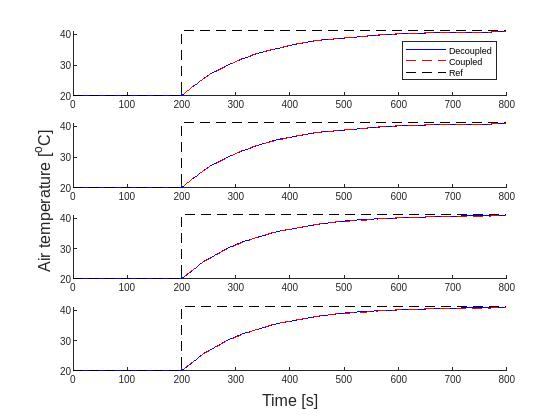

ans = struct with fields:
    time: [53×1 double]
      Tw: [53×4 double]
      Ta: [53×4 double]
       T: [53×4 double]


util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Wref_and_Wz",0,800,21)

## Simulate the flow for going to 35 and 10 degrees

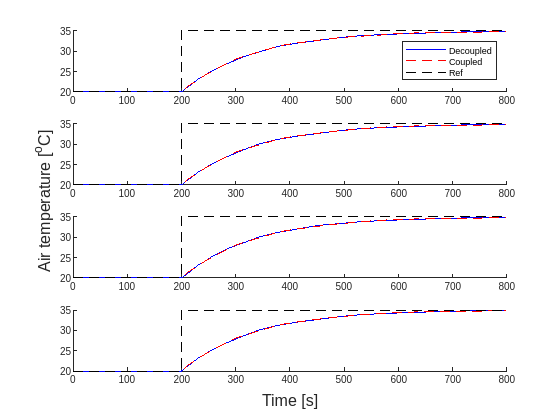


[decoupleResult, CoupledResults] = util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Wref_and_Wz_30",0,800,15);

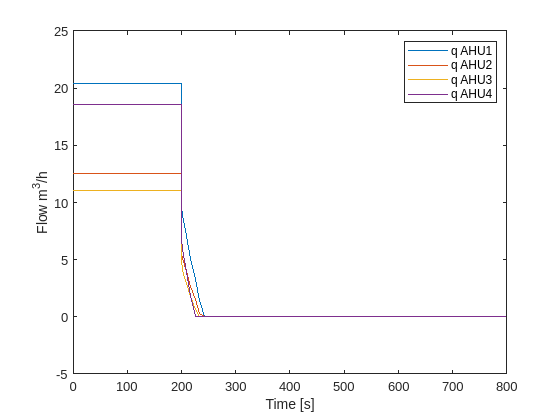

figure()
plot(CoupledResults.time,CoupledResults.q'*3600);
legend("q AHU1","q AHU2","q AHU3","q AHU4")
xlabel("Time [s]")
ylabel("Flow m^3/h")
saveas(gcf,"Images/FlowIncreaseTempBy10Deg","epsc")

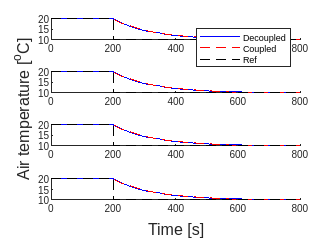

[decoupleResult, CoupledResults] = util.SimulateLinearStep(param,"Synthesis_Of_DesiredPerformance_Wref_and_Wz_10",0,800,-10);

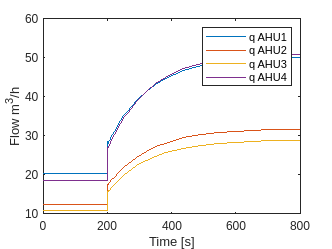

figure()
plot(CoupledResults.time,CoupledResults.q'*3600);
% yline(param.ctrl.q_OP,"--b")
legend("q AHU1","q AHU2","q AHU3","q AHU4")
xlabel("Time [s]")
ylabel("Flow m^3/h")
saveas(gcf,"Images/FlowLowerTempBy10Deg","epsc")

## Verify robust stability

By calculating Mw and taking the Hinfnorm the robust stability can be verified 

Mw = model.calculateMw(param);
hinfnorm(Mw)

ans = 0.2282